# LSUN POD OnlineDMD for dynamic system prediction

clear 
close all 

## Parameter Setup

maxtimes = 1;
totalerr_pod = zeros(1,maxtimes);
totalerr_LSUN = zeros(1,maxtimes);
for exptimes = 1:maxtimes
% nrows = 199;
% ncols = 449;
% load("../../../data/databook_DATA/DATA/VORTALL");
% ut = reshape(VORTALL,nrows,ncols,[]);
%testdata = ut;
load('SampleN2DS_2.mat');
testdata = SampleN2DS_2;
% load("SampleN2DF_2.mat");
% testdata = SampleN2DF_2;
[nrows,ncols,fullstep] = size(testdata);
dt = 100;%check
trnstep = 200;%check
eststep = fullstep - trnstep;
nrows4PODtrunc = 5; %r----check
step = 10;  %%(k+1)----check
ro = 0.9;%%rho

## Noisy Data Preparation

trandata = testdata;
varu = var(trandata,0,'all');
varw = 0.4*varu; %%%check
sigmaw = sqrt(varw);
trandata = trandata + sigmaw * randn(size(trandata),'like',trandata);

Xorg = reshape(trandata,[],fullstep);
Xtest = reshape(testdata,[],fullstep);

## Experiments

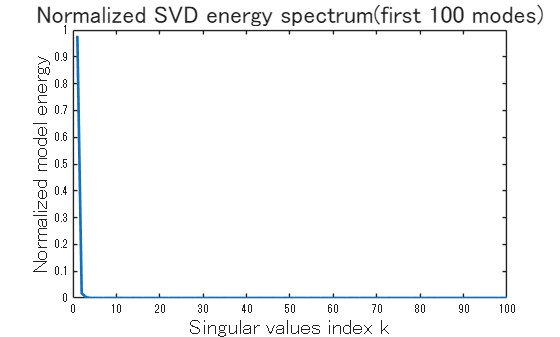

%Singular values
[~, Ss, ~] = svd(Xtest, 'econ');
sigma = diag(Ss);
energy = sigma.^2 / sum(sigma.^2);
plot(energy,'-','LineWidth',2)
axis([0 100 0 1])
xlabel('Singular values index k','FontSize',16)
ylabel('Normalized model energy','FontSize',16)
title('Normalized SVD energy spectrum(first 100 modes)','FontSize',18)


## Dimensional reduction via LSUN

- Train LSUN 

- Project data onto the LSUN feature space

### Train LSUN

% Decimation factor (Strides)
blksz = 4.*[1 1]; % Block size
stride = blksz; % [My Mx]
% Number of overlapping blocks (Polyphase order plus one)
nof = 1;
ky = 2*nof+1; % # of overlapping blocks (odd number)
kx = 2*nof+1;
ovlpFactor = [ky kx];
% # of coeffs
nCoefs = 1;
% Max epochs
maxEpochs = 8;
% Mini batch size
miniBatchSize = 5;
% Standard deviation of initial angles
stdInitAng = 1e-6;
% No DC-leakage
noDcLeakage = false;
strbuf = "";
strbuf = strbuf.append(sprintf('---- LSUN Parametars -----------------------     \n'));
strbuf = strbuf.append(sprintf('Block size                           [%d %d]  \n',blksz));
strbuf = strbuf.append(sprintf('Strides                              [%d %d]  \n',stride));
strbuf = strbuf.append(sprintf('Overlapping blocks                   [%d %d]  \n',ky,kx));
strbuf = strbuf.append(sprintf('nCoef                                [%d]     \n',nCoefs));
strbuf = strbuf.append(sprintf('Max epochs                           [%d]     \n',maxEpochs));
strbuf = strbuf.append(sprintf('Mini batch size                      [%d]     \n',miniBatchSize));
strbuf = strbuf.append(sprintf('Standard deviation of initial angles [%d]     \n',stdInitAng));
strbuf = strbuf.append(sprintf('No DC-leakage                        [%d]     \n',noDcLeakage));
strbuf = strbuf.append(sprintf('--------------------------------------------     \n'));
disp(strbuf)

---- LSUN Parametars -----------------------     
Block size                           [4 4]  
Strides                              [4 4]  
Overlapping blocks                   [3 3]  
nCoef                                [1]     
Max epochs                           [8]     
Mini batch size                      [5]     
Standard deviation of initial angles [1.000000e-06]     
No DC-leakage                        [0]     
--------------------------------------------     



### Pad array

szy = ceil(nrows/blksz(1))*blksz(1);
szx = ceil(ncols/blksz(2))*blksz(2);
% Pad zeros to make the size multiples of nDecs.
trandatapad = padarray(trandata,[szy szx]-[nrows ncols],0,'post');

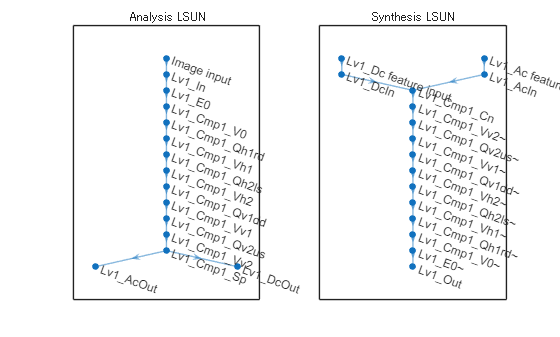

import tansacnet.lsun.*
analysislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
synthesislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis LSUN')

### Construction of synthesis/analysis network

% Construction of synthesis network.
analysisnet = dlnetwork(analysislgraph);

% Initialize
nLearnables = height(analysisnet.Learnables);
for iLearnable = 1:nLearnables
    if analysisnet.Learnables.Parameter(iLearnable)=="Angles"
        analysisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end
    
import tansacnet.lsun.*
% Construction of analysis network
analysislgraph = layerGraph(analysisnet);
synthesislgraph = fcn_cpparamsana2syn(synthesislgraph,analysislgraph);
synthesisnet = dlnetwork(synthesislgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~


### Confirmation of the adjoint relation (perfect reconstruction)

x = rand([szy szx],'double');
dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

    "MSE: 3.9348e-10"



## Parameter optimization and approximation

### Create analysis layerGraph

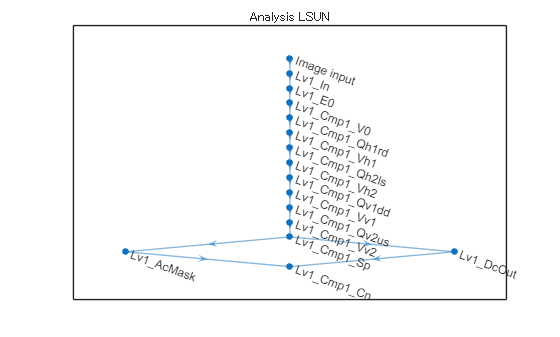

import tansacnet.lsun.*
analysislgraph = layerGraph(analysisnet);

% Coefficient masking
nChsTotal = prod(stride);
coefMask = [ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)];
coefMask = [coefMask(1:2:end); coefMask(2:2:end)];
%nLevels = 1;
%for iLv = nLevels:-1:1
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
analysislgraph = analysislgraph.replaceLayer([strLv 'AcOut'],...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
%strLvPre = strLv;
%end

% Output layer
iCmp = 1;
strCmp = sprintf('Cmp%0d_',iCmp);
%analysislgraph = analysislgraph.addLayers([...
%      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']) ...
%      lsunRegressionLayer('Coefficient output')
%     ]);
analysislgraph = analysislgraph.addLayers(...
      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']));
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'AcMask' ], [strLv strCmp 'Cn/ac']);
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'DcOut' ], [strLv strCmp 'Cn/dc']);

figure
plot(analysislgraph)
title('Analysis LSUN')

### Training Data Set

% Image data store
arrds = arrayDatastore(trandatapad(:,:,1:end-1),'IterationDimension',3);
% figure
% dataOut = preview(arrds);
% tile = imtile(dataOut);
% mycylinderplot_([],tile,clims);
% drawnow

## Training phase

numimgs = fullstep-1;
mbq = minibatchqueue(arrds,...
    'MiniBatchSize',miniBatchSize,...
    'OutputAsDlarray',1,...
    'MiniBatchFcn',@preprocessMiniBatch,...
    'MiniBatchFormat','SSCB',...
    'OutputCast','double',...
    'OutputEnvironment','gpu');
shuffle(mbq)
dlX = next(mbq);
trainnet = dlnetwork(analysislgraph,dlX);
trainnet.Initialized   

ans = logical
   1


% Configuration
figure
lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

velocity = [];
iteration = 0.01;
momentum = 0.9;
decay = 0.01;
initialLearnRate = 1e-4;

% Loop over epochs.
start = tic;
for epoch = 1:maxEpochs

    % Shuffle data.
    shuffle(mbq)

    while hasdata(mbq)
        % Loop over mini-batches.
        iteration = iteration + 1;
    
        % Read mini-batch of data.
        dlX = next(mbq);

        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [gradients,loss] = dlfeval(@modelGradients,trainnet,dlX);
        
        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + decay*iteration);

        % Update the network parameters using the SGDM optimizer.
        [trainnet,velocity] = sgdmupdate(trainnet,gradients,velocity,learnRate,momentum);

        % Display the training progress.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        addpoints(lineLossTrain,iteration,loss)
        title("Epoch: " + epoch + ", Elapsed: " + string(D))
        drawnow
    end
end


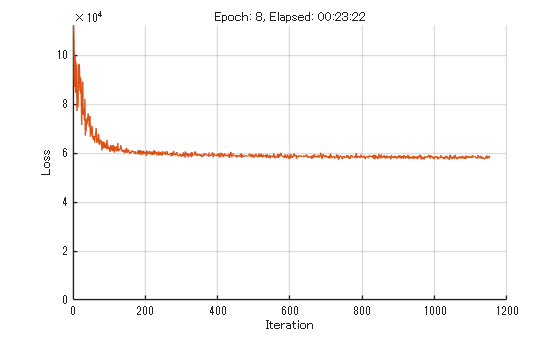

% lsunresfile = "../../../results/lsun4pod"+string(datetime('now','TimeZone','local','Format','yyyy-M-dd-HH-mm-ssZ'))

% save(lsunresfile,"trainnet","szy","szx","nCoefs");

## Inference phase

%lsunresfile = "../../../results/lsun4pidmd2024-3-11-06-07-39+0900";
%load(lsunresfile)

### Construction of LSUN-base linear autoencoder 

nLevels = extractnumlevels(trainnet);
stride = extractstride(trainnet);
ovlpFactor = extractovlpfactor(trainnet);
noDcLeakage = extractnodcleakage(trainnet);
szExt = [szy szx];
strbuf = "";
strbuf = strbuf.append(sprintf('---- LSUN Parametars -----------------------     \n'));
strbuf = strbuf.append(sprintf('Strides                              [%d %d]  \n',stride));
strbuf = strbuf.append(sprintf('Overlapping blocks                   [%d %d]  \n',ovlpFactor(1),ovlpFactor(2)));
strbuf = strbuf.append(sprintf('nCoef                                [%d]     \n',nCoefs));
strbuf = strbuf.append(sprintf('No DC-leakage                        [%d]     \n',noDcLeakage));
strbuf = strbuf.append(sprintf('Extended size                        [%d %d]  \n',szy,szx));
strbuf = strbuf.append(sprintf('--------------------------------------------  \n'));
disp(strbuf)

---- LSUN Parametars -----------------------     
Strides                              [4 4]  
Overlapping blocks                   [3 3]  
nCoef                                [1]     
No DC-leakage                        [0]     
Extended size                        [72 204]  
--------------------------------------------  



Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2


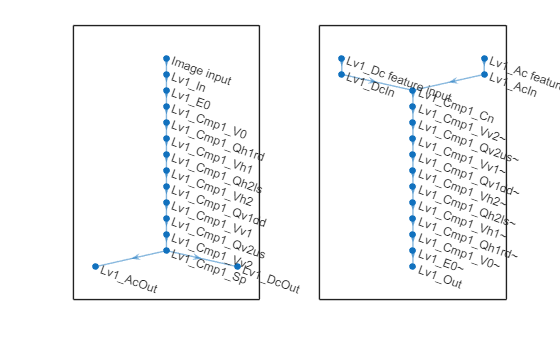

import tansacnet.lsun.*
lsunana4predict = fcn_createlsunlgraph2d([],...
    'InputSize',szExt,...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
lsunsyn4predict = fcn_createlsunlgraph2d([],...
    'InputSize',szExt,...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
trainlgraph = layerGraph(trainnet);
lsunsyn4predict = fcn_cpparamsana2syn(lsunsyn4predict,trainlgraph);

lsunana4predict = fcn_cpparamssyn2ana(lsunana4predict,lsunsyn4predict);
figure
subplot(1,2,1)
plot(lsunana4predict)
subplot(1,2,2)
plot(lsunsyn4predict)

## Linear autoencoder with LSUN

### Assemble analyzer

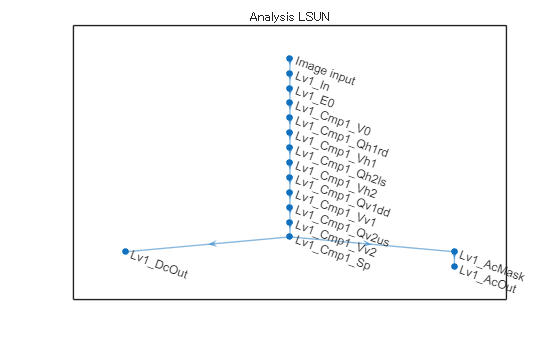

% Coefficient masking
nChsTotal = prod(stride);
isPR = false;
if isPR
    nCoefs = nChsTotal;
end
coefMask = [ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)];
coefMask = [coefMask(1:2:end); coefMask(2:2:end)];

iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
lsunana4predict = lsunana4predict.disconnectLayers([strLv 'Cmp1_Sp/ac'],[strLv 'AcOut']);
lsunana4predict = lsunana4predict.addLayers(...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
lsunana4predict = lsunana4predict.connectLayers(...
    [strLv 'Cmp1_Sp/ac'],[strLv 'AcMask']);
lsunana4predict = lsunana4predict.connectLayers(...
    [strLv 'AcMask'],[strLv 'AcOut']);
for iLayer = 1:height(lsunana4predict.Layers)
    layer = lsunana4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        lsunana4predict = lsunana4predict.replaceLayer(layer.Name,...
            regressionLayer('Name',layer.Name));
    end
end

figure
plot(lsunana4predict)
title('Analysis LSUN')
analysislsun4predict = assembleNetwork(lsunana4predict);

### Assemble synthesizer 

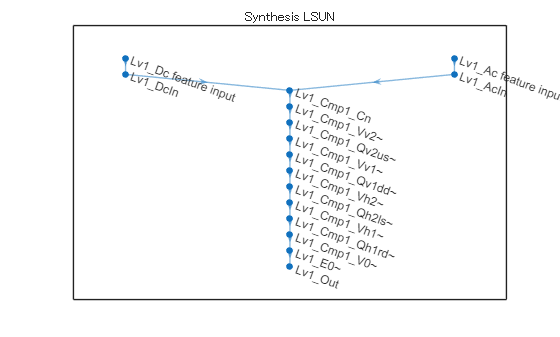

lsunsyn4predict = lsunsyn4predict.replaceLayer('Lv1_Out',...
    regressionLayer('Name','Lv1_Out'));
for iLayer = 1:height(lsunsyn4predict.Layers)
    layer = lsunsyn4predict.Layers(iLayer);
    if contains(layer.Name,'Ac feature input')
        iLv = str2double(layer.Name(3));
        sbSize = szExt.*(stride.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize (sum(nChsTotal)-1)],'Name',layer.Name,'Normalization','none');
        lsunsyn4predict = lsunsyn4predict.replaceLayer(...
            layer.Name,newlayer);
    elseif contains(layer.Name,sprintf('Lv%0d_Dc feature input',nLevels))
        iLv = str2double(layer.Name(3));
        sbSize = szExt.*(stride.^(-iLv));
        newlayer = ...
            imageInputLayer([sbSize 1],'Name',layer.Name,'Normalization','none');
        lsunsyn4predict = lsunsyn4predict.replaceLayer(...
            layer.Name,newlayer);
    end
end

figure
plot(lsunsyn4predict)
title('Synthesis LSUN')
synthesislsun4predict = assembleNetwork(lsunsyn4predict);

### Check reconstruction

analysislsun4predict.Layers
synthesislsun4predict.Layers

ans =   次の層をもつ 16×1 の Layer 配列:

     1   'Image input'      イメージの入力                                      72×204×1 イメージ
     2   'Lv1_In'           tansacnet.lsun.lsunIdentityLayer                 Identity
     3   'Lv1_E0'           tansacnet.lsun.lsunBlockDct2dLayer               Block DCT of size 4x4
     4   'Lv1_Cmp1_V0'      tansacnet.lsun.lsunInitialRotation2dLayer        LSUN initial rotation (ps,pa) = (8,8), (mv,mh) = (4,4)
     5   'Lv1_Cmp1_Qh1rd'   tansacnet.lsun.lsunAtomExtension2dLayer          Right shift the difference-channel Coefs. (ps,pa) = (8,8)
     6   'Lv1_Cmp1_Vh1'     tansacnet.lsun.lsunIntermediateRotation2dLayer   Analysis LSUN intermediate rotation (ps,pa) = (8,8)
     7   'Lv1_Cmp1_Qh2ls'   tansacnet.lsun.lsunAtomExtension2dLayer          Left shift the sum-channel Coefs. (ps,pa) = (8,8)
     8   'Lv1_Cmp1_Vh2'     tansacnet.lsun.lsunIntermediateRotation2dLayer   Analysis LSUN i

ans =   次の層をもつ 16×1 の Layer 配列:

     1   'Lv1_DcIn'               tansacnet.lsun.lsunComponentSeparation2dLayer    tansacnet.lsun.lsunComponentSeparation2dLayer
     2   'Lv1_AcIn'               tansacnet.lsun.lsunComponentSeparation2dLayer    tansacnet.lsun.lsunComponentSeparation2dLayer
     3   'Lv1_Cmp1_Cn'            tansacnet.lsun.lsunChannelConcatenation2dLayer   Channel concatenation
     4   'Lv1_Cmp1_Vv2~'          tansacnet.lsun.lsunIntermediateRotation2dLayer   Synthesis LSUN intermediate rotation (ps,pa) = (8,8)
     5   'Lv1_Cmp1_Qv2us~'        tansacnet.lsun.lsunAtomExtension2dLayer          Down shift the sum-channel Coefs. (ps,pa) = (8,8)
     6   'Lv1_Cmp1_Vv1~'          tansacnet.lsun.lsunIntermediateRotation2dLayer   Synthesis LSUN intermediate rotation (ps,pa) = (8,8)
     7   'Lv1_Cmp1_Qv1dd~'        tansacnet.lsun.lsunAtomExtension2dLayer          Up shift the difference-channel Coef

    "MSE: 4.0043"



### Pad array

szy = ceil(nrows/blksz(1))*blksz(1);
szx = ceil(ncols/blksz(2))*blksz(2);
% Pad zeros to make the size multiples of nDecs.
vtpad = padarray(trandata,[szy szx]-[nrows ncols],0,'post');

if isPR 
    x = gpuArray(randn(szy,szx,'double'));
else
    x = gpuArray(vtpad(:,:,1));
end
[s{1:nLevels+1}] = analysislsun4predict.predict(x);
y = synthesislsun4predict.predict(s{nLevels+1:-1:1}); % FIXME: Order of AC & DC should be flipped
if isPR
    display("MSE: " + num2str(mse(x,y)))
else
    xor= trandata(:,:,1);
    yapx = y(1:nrows,1:ncols);
    display("MSE: " + num2str(mse(xor,yapx)))
end

totalerr_LSUN = 0.5248

## Define the LSUN analyzer and synthesizer

nLayers = height(analysislsun4predict.Layers);
for iLayer = 1:nLayers
    layer = analysislsun4predict.Layers(iLayer);
    if strcmp(layer.Name,"Lv1_AcMask")
        acMask = logical(squeeze(layer.Mask));
    end
end
analyzer_ = @(x) fcn_lsunanalyzer_(x,analysislsun4predict,acMask); % Analyze array x, and vectorize the result
synthesizer_ = @(x) fcn_lsunsynthesizer_(x,synthesislsun4predict,acMask); %nFrames Reshape x and synthesize the result 
vtpad = gpuArray(vtpad);
Xlsun = analyzer_(vtpad); 

%%LSUN POD Online DMD
init_ldata = Xlsun(:,1:step);
[Uxl,Sxl,Vxl] = svd(init_ldata,"econ");
Uxl = Uxl(:,1:nrows4PODtrunc);
Sxl = Sxl(1:nrows4PODtrunc,:);
Txl = Sxl * Vxl';
init_xl = Txl(:,1:end-1);
init_yl = Txl(:,2:end);
lodmd = OnlineDMD(nrows4PODtrunc,ro);
lodmd.initialize(init_xl,init_yl);
for count = 1+step:1:fullstep-1
    vtl = Xlsun(:,count-nrows4PODtrunc+1:count);     
    [Uxl,Sxl,Vxl] = svd(vtl,"econ");
    Txl = Sxl * Vxl';
    up_xl = Txl(:,end-1);
    up_yl = Txl(:,end);
    lodmd.update(up_xl,up_yl);
    Rlpod(:,count+1) = Uxl * lodmd.A * up_yl;
end
rtpad = synthesizer_(Rlpod(:,step+2:end));
rtlsun = rtpad(1:nrows,1:ncols,:);
rtlpod = reshape(rtlsun,[],size(rtlsun,3));
err_lp = rmse(Xtest(:,step+2:end),rtlpod);
totalerr_LSUN(exptimes) = mean(err_lp)

totalerr_pod = 1.3787

%%LSUN+DMD
Xdmd = Xlsun(:,1:trnstep-1);
Ydmd = Xlsun(:,2:trnstep);
r_d = rank(Xdmd);
[Phi_dmd_d,omega_d,lambda_d] = fcn_DMD(Xdmd,Ydmd,r_d,dt);
b_d = Phi_dmd_d \ Ydmd(:,end);
    for step_e = 1:eststep
         Rldmd(:,step_e) = real(Phi_dmd_d * (exp(omega_d*step_e*dt).*b_d)); % Take real only for numerical error correction 
    end 
rpidmdpad = synthesizer_(Rldmd);
rtpidmd = rpidmdpad(1:nrows,1:ncols,:);
rpidmd = reshape(rtpidmd,[],size(rtpidmd,3));
tdata_d = Xtest(:,trnstep+1:fullstep);
err_ld = rmse(tdata_d,rpidmd);

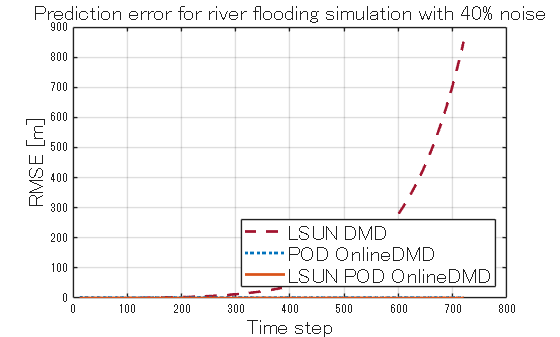

%%POD+onlineDMD
init_data = Xorg(:,1:step);
[Ux,Sx,Vx] = svd(init_data,"econ");
Ux = Ux(:,1:nrows4PODtrunc);
Sx = Sx(1:nrows4PODtrunc,:);
Tx = Sx * Vx';
init_x = Tx(:,1:end-1);
init_y = Tx(:,2:end);

odmd = OnlineDMD(nrows4PODtrunc,ro);
odmd.initialize(init_x,init_y);
for count = 1+step:1:fullstep-1
    vt = Xorg(:,count-nrows4PODtrunc+1:count);
    [Ux,Sx,Vx] = svd(vt,"econ");
    Tx = Sx * Vx';
    up_x = Tx(:,end-1);
    up_y = Tx(:,end);
    odmd.update(up_x,up_y);
    Rpod(:,count+1) = Ux * odmd.A * up_y;
    tdata_p = Xtest(:,count+1);
    err_p(count+1) = rmse(tdata_p,Rpod(:,count+1));
end
totalerr_pod(exptimes) = mean(err_p(step+2:end))
end

## Plot results

timeSet = step+2:1:fullstep;
timeSet2 = trnstep+1:1:fullstep;

plot(timeSet2,err_ld,...
    '--','Color','#A2142F','LineWidth',2,...
        'DisplayName','LSUN DMD')
hold on

plot(timeSet,err_p(step+2:end),...
    ':','Color','#0072BD','LineWidth',2,...
        'DisplayName','POD OnlineDMD')

plot(timeSet,err_lp,...
        '-','Color','#D95319','LineWidth',2,...
        'DisplayName','LSUN POD OnlineDMD')

xlabel('Time step','FontSize',16);
ylabel('RMSE [m]','FontSize',16);
title('Prediction error for river flooding simulation with 40% noise','FontSize',16)
grid on
lgd = legend('Location','southeast');
lgd.FontSize = 16;
hold off

## Local functions

### LSUN Analyzer

function Xlsun = fcn_lsunanalyzer_(x,analyzer,acMask)
nFrames = size(x,3);
nLevels = 1;
szy = size(x,1);
szx = size(x,2);
stride = extractstride(analyzer);
Xlsun = zeros(szy*szx*(1+sum(acMask))/prod(stride),nFrames,'like',x);
for iFrame = 1:nFrames
    [s{1:nLevels+1}] = analyzer.predict(x(:,:,iFrame));
    dc = s{1};
    ac = s{end};
    ac = ac(:,:,acMask); % Shrink
    Xlsun(:,iFrame) = reshape(cat(3,dc,ac),[],1);
end
end

### LSUN Synthesizer

function x = fcn_lsunsynthesizer_(Xlsun,synthesizer,acMask)
nLevels = 1;
nLayers = height(synthesizer.Layers);
for iLayer = 1:nLayers
    layer = synthesizer.Layers(iLayer);
    if strcmp(layer.Name,"Lv1_Ac feature input")
        szac = layer.InputSize;
    end
end
nFrames = size(Xlsun,2);
stride = extractstride(synthesizer);
x = zeros(szac(1)*stride(1),szac(2)*stride(2),nFrames);
s = cell(nLevels+1,1);
ac = zeros(szac,'like',Xlsun);
for iFrame = 1:nFrames
    xlsun = reshape(Xlsun(:,iFrame),szac(1),szac(2),[]);
    s{1} = xlsun(:,:,1);
    % Extension
    ac(:,:,acMask) = xlsun(:,:,2:end);
    s{nLevels+1} = ac;
    x(:,:,iFrame) = synthesizer.predict(s{nLevels+1:-1:1});
end
end

### Definition of Drawing Function

function him = mycylinderplot_(him,x,clims)
if isempty(him)
    figure
    him = imagesc(x,clims);
    axis equal
    axis tight
    ax = gca;
    ax.XTick = [];
    ax.YTick = [];
    cmap = zeros(256,3);
    cmap(128:255,1) = 1;
    cmap(1:127,3) = 1;
    hsv = rgb2hsv(permute(cmap,[1 3 2]));
    hsv(:,2) = [254:-2:0 1:2:255].'/255;
    cmap = ipermute(hsv2rgb(hsv),[1 3 2]); 
    colormap(cmap)
else
    him.CData = x;
end
end

### Gradients w.r.t. LSUN design parameters

function [gradients, loss] = modelGradients(dlnet, dlX)
% Forward data through the dlnetwork object.
dlY = forward(dlnet,dlX); % F(x)
% Compute loss.
Nx = size(dlX,4);
Ny = size(dlY,4);
loss = sum(dlX.^2,"all")/Nx-sum(dlY.^2,"all")/Ny;
% Compute gradients.
gradients = dlgradient(loss,dlnet.Learnables);
loss = double(gather(extractdata(loss)));
end

### MiniBatch function

function X = preprocessMiniBatch(XCell)
    % Extract image data from the cell array and concatenate over fourth
    % dimension to add a third singleton dimension, as the channel
    % dimension.
    X = cat(4,XCell{:});
end

### Information extractors

function nLevels = extractnumlevels(lsun)
import tansacnet.lsun.*

% Extraction of information
expidctlayer = '^Lv\d+_E0~?$';
nLevels = 0;
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expidctlayer,'once'))
        nLevels = nLevels + 1;
    end
end
end

function stride = extractstride(lsun)
import tansacnet.lsun.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        stride = layer.Stride;
    end
end
end

function ovlpFactor = extractovlpfactor(lsun)
import tansacnet.lsun.*

% Extraction of information
expanalyzerv = '^Lv\d+_Cmp\d+_Vv(\d)+$';
expanalyzerh = '^Lv\d+_Cmp\d+_Vh(\d)+$';
nLayers = height(lsun.Layers);
ovlph = 1;
ovlpv = 1;
for iLayer = 1:nLayers
    alayer = lsun.Layers(iLayer);
    alayerName = alayer.Name;
    if ~isempty(regexp(alayerName,expanalyzerv,'once'))
        ovlpv = ovlpv + 1;
    elseif ~isempty(regexp(alayerName,expanalyzerh,'once'))
        ovlph = ovlph + 1;
    end
end

ovlpFactor = [ovlpv ovlph];

end

function noDcLeakage = extractnodcleakage(lsun)
import tansacnet.lsun.*

% Extraction of information
expfinallayer = '^Lv1_Cmp1+_V0~?$';
nLayers = height(lsun.Layers);
for iLayer = 1:nLayers
    layer = lsun.Layers(iLayer);
    if ~isempty(regexp(layer.Name,expfinallayer,'once'))
        noDcLeakage = layer.NoDcLeakage;
    end
end

end